# Practice Problem 1

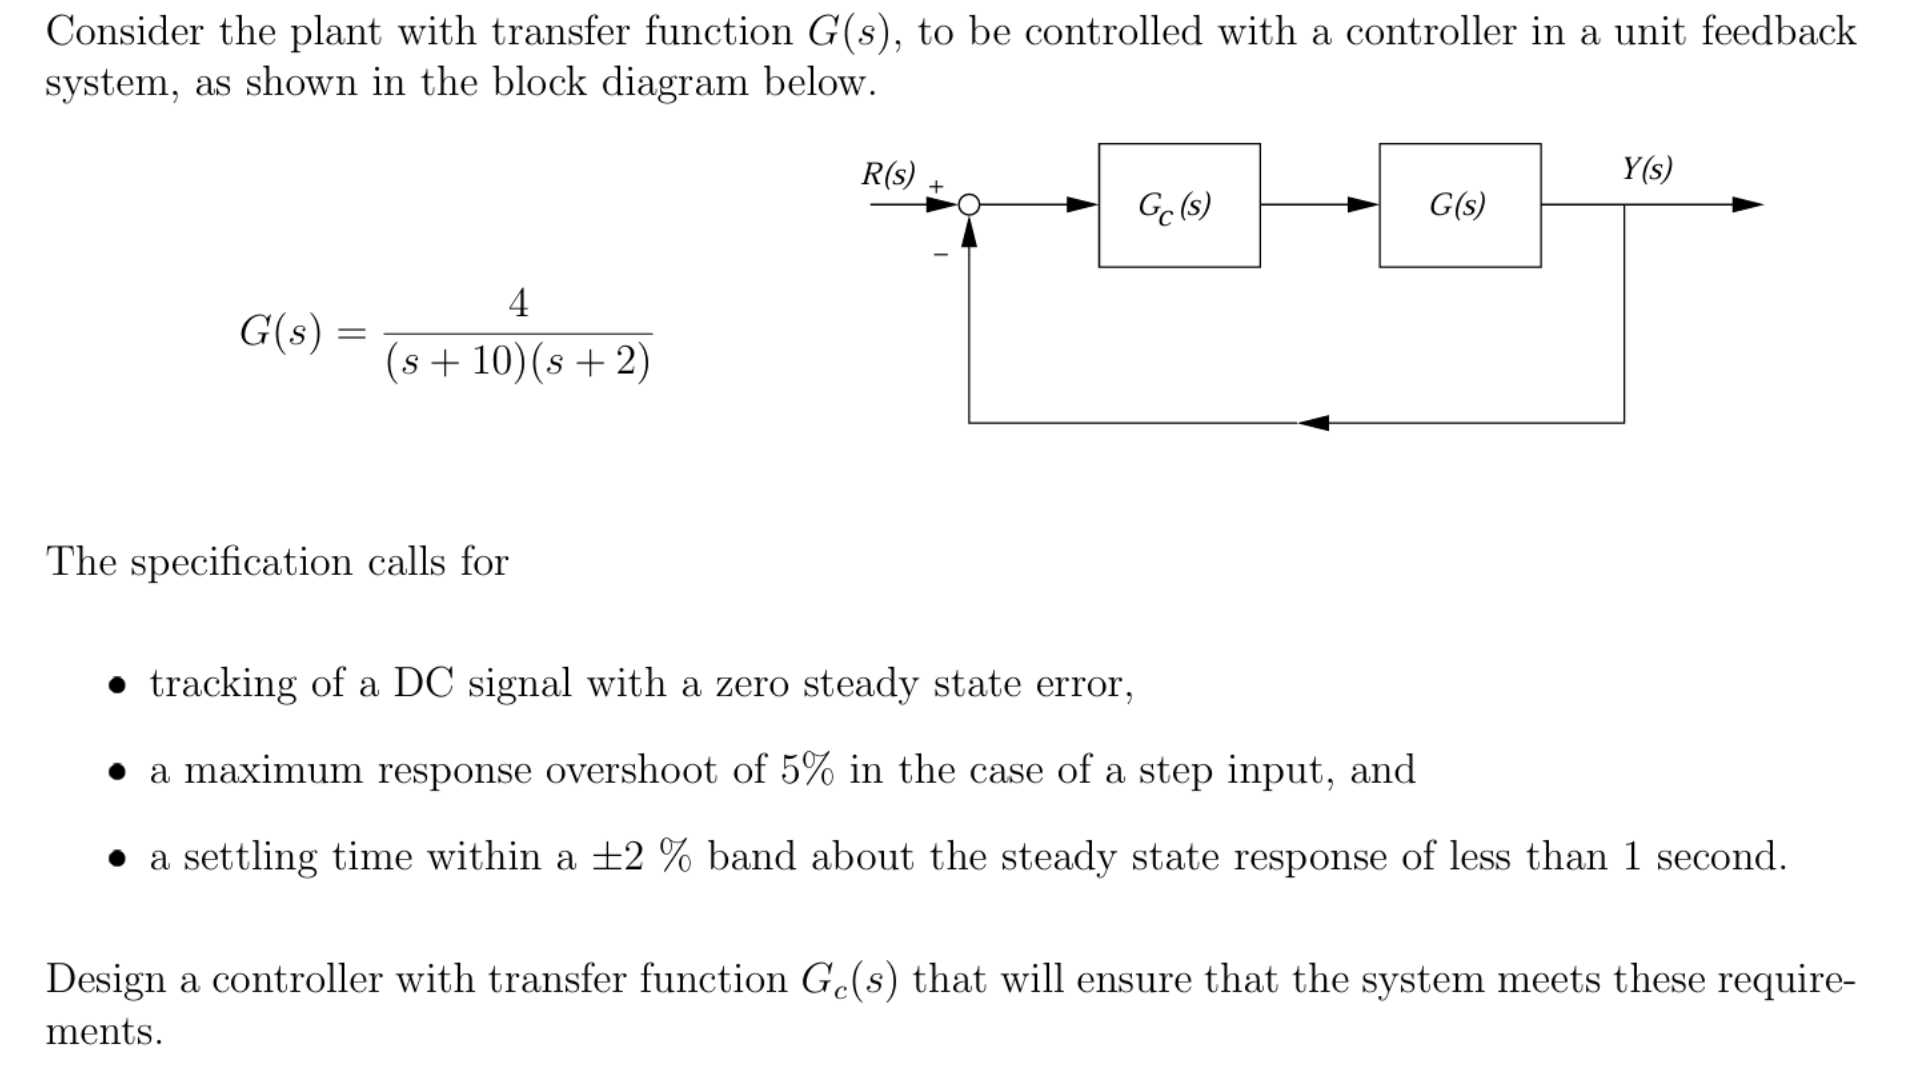

clearvars, clc, close all
Gpoles = [-10, -2]

Gpoles =    -10    -2


G = zpk([],Gpoles,4.0)


G =
 
       4
  ------------
  (s+10) (s+2)
 
Continuous-time zero/pole/gain model.


T = feedback(G,1)


T =
 
           4
  -------------------
  (s+2.536) (s+9.464)
 
Continuous-time zero/pole/gain model.


tt = linspace(0.0,8.0,200);
y = step(T,tt);
figure(1)
plot(tt,y)
hold on
plot([tt(1), tt(end)],[1.05, 1.05],'g')
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([1,1],[0,1.6],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')

Since overshoot $M_p \le 0\ldotp 05$


$$M_p =e^{-\frac{\pi \zeta }{\sqrt{1-\zeta^2 }}}$$


solving for $\zeta \approx 0\ldotp 6901$, so $\zeta \ge 0\ldotp 69$

According to [Franklin](https://moodle.gtiit.edu.cn/moodle/pluginfile.php/234230/mod_page/content/1/Feedback%20Control%20of%20Dynamic%20Systems%208th%20Ed.pdf) Fig 3.24 we can directly find the value of $\zeta =0\ldotp 7$

Settling time:

 
$${e^{-\zeta \;\omega_n t_s } =0\ldotp 02\to \;t}_s \approx \frac{4}{\omega_n \zeta }$$


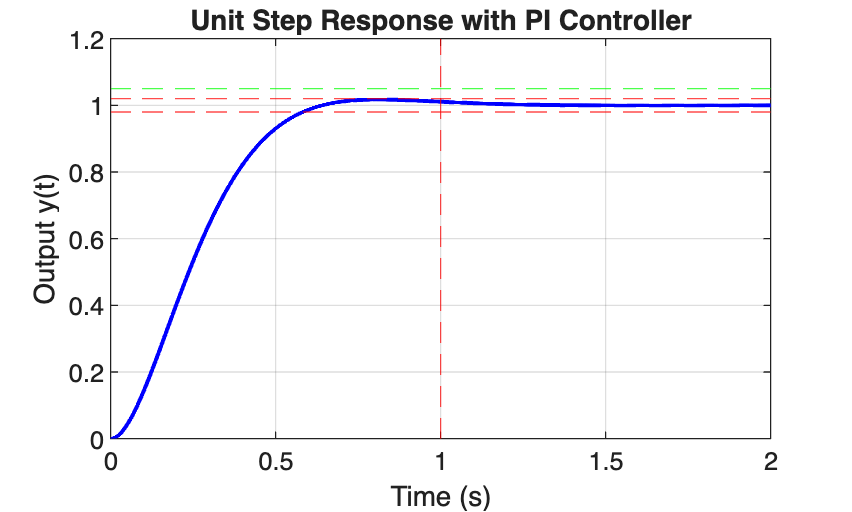

clearvars; clc; close all;

%% Plant
Gpoles = [-10, -2];
G = zpk([], Gpoles, 4);

%% PI Controller
s = tf('s');

Kp = 10;
Ki = 20;

Gc = Kp + Ki/s;

%% Closed-loop transfer function
T = feedback(Gc*G, 1);

%% Step response
tt = linspace(0, 2, 2000);
y = step(T, tt);

figure(1)
plot(tt, y, 'b', 'LineWidth', 1.5)
hold on

% 5% overshoot limit
yline(1.05, 'g--');

% 2% settling band
yline(1.02, 'r--');
yline(0.98, 'r--');

% Settling time requirement
xline(1, 'r--');

grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit Step Response with PI Controller')


%% Performance evaluation
info = stepinfo(T);

fprintf('Overshoot = %.4f %%\n', info.Overshoot);

Overshoot = 1.7322 %


fprintf('Settling time = %.4f s\n', info.SettlingTime);

Settling time = 0.5824 s


fprintf('Steady-state error = %.6f\n', abs(1-dcgain(T)));

Steady-state error = 0.000000



%% Simplified transfer function
disp('Closed-loop transfer function:')

Closed-loop transfer function:


minreal(T)


ans =
 
         40
  ----------------
  (s^2 + 10s + 40)
 
Continuous-time zero/pole/gain model.
